# F2_Run_4D_Sensitivity.m

**Goal**: Generate 1D sensitivity analysis on probiotic parameters starting with the "null" probiotic. The "null" probiotic is defined as having a moderate growth rate (0.5) and all interspecies interaction terms as zero.

**Requirements:** 

MATLAB Toolboxes: Parallel Computing, Bioinformatics, Symbolic Math

Custom Scripts: Add the `probiotic_code/` folder to your path

Model inputs as defined in `define_Common_Simulation_Inputs `(*Defines virtual patient population, simulation inputs)*

*Functions:*` simulate_CST_probiotic_object.m, plot_4D_SensitivityAnalysis.m`

## 1.LOAD MODEL DEFAULTS

clear; clc;
output_fdr = 'result_workspaces/';
ws_name = 'input_files/SSConfig-Analysis-HMP-Virtual-Population.mat';
simulationType = "base";
[POPinfo,PROBinfo,~,SIMinfo] = define_Common_Simulation_Inputs(ws_name,simulationType);
[param_names,~,sp_cols,~] = get_naming_terms();

`POPinfo`: struct that defines virtual patient population

- `virtualPatientParameter`s: # patients x 20 parameter matrix generated by LHS

- `virtualPatientComposition`: 1 x # patients cell of analytically predicted steady-state absolute abundances of nAB, Li, oLB (predicted without considering probiotic in community)

`PROBinfo`: struct that defines probiotic parameters

- dose: absolute abundance of probiotic when dosed into the base community (selected from relative abundance data observed in Dausset et al. 2018)

- numberDoses: total number of doses given

- doseFrequency: time separation (days) between each dose

`SIMinfo`: struct that defines simulation inputs

- `startProbiotic`: time point after simulation begins to start probiotic therapy

- `stopSimulation`: time point to end simulation relative to the last day of probiotic treatment

- ` initialComposition`: scaling factor to "displace" from the predicted composition (POPinfo.virtualPatientComposition). For example, 0.01 is a 1% decrease in abundance and 0.05 is a 0.5% increase from the predicted abundance

- `alteredParamIndex`: indexes of probiotic-related parameters relative to the full parameter list

- `paramAlteration`: new value for probiotic parameters (a 1 x length alteredParamIndex array of values)

- `paramAlterationType`: 'None' (use LHS probiotic parameter, ignore paramAlteration values), 'fold addition' (scale LHS probiotic parameter (LP) + paramAlteration * LP,  'absolute' (set to exact value in paramAlteration)

- `ODEoptions`: "options" input for ode solvers

- `ODEsolver:` ODE solver function handle (e.g., @ode45, @ode15s)

## 2. RUN 4D SENSITIVITY ANALYSIS

% DEFINE THE 4 PARAMETERS TO ALTER
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
base_params = [0.5 0 0 0 0 0 0 -0.022]; % base parameter set
pmags1 = [-0.01 0 0.01]; % magnitudues for the parameter alteration
pidx = [8 17 18 19]; % indexes of parameter combinations
output_ws_nm = 'F2_4D_Sensitivity.mat';

vectorCell = {[pmags1],[pmags1],[pmags1],[pmags1]};
[newValueMat] = generate_input_combos(vectorCell);
fullparamChange = zeros(size(newValueMat,1),length(base_params));
fullparamChange(:,1) = base_params(1);
fullparamChange(:,end) = base_params(end);
fullparamChange(:,[2,5,6,7]) = newValueMat;

% RUN ALL COMBINATIONS OF ALTERATION
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
numVirtualPatients = length(POPinfo.virtualPatientComposition);
all_select_outcomes = NaN(size(newValueMat,1),numVirtualPatients,8,5);
all_warnall = NaN(size(newValueMat,1),numVirtualPatients);
c = 1;
for pert_id = 1:size(newValueMat,1)
    SIMinfo.paramAlteration = fullparamChange(pert_id,:);
    [select_outcomes,~,~,~,warnall,~] = simulate_CST_probiotic_object(POPinfo,PROBinfo,SIMinfo);
    all_select_outcomes(pert_id,:,:,:) = select_outcomes;
    all_warnall(pert_id,:) = warnall == "";


    % Pause simulations for 1 minute, every 10 iterations
    c = c + 1;
    if c == 10
        save(strcat(output_fdr,output_ws_nm),'all_select_outcomes','all_warnall',...
            'POPinfo','PROBinfo','SIMinfo','base_params',...
            "all_warnall", 'pert_id','newValueMat','pidx')
        c = 1; pause(60);
    end
end

> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)
> In ode15s (line 715)
  In parallel_function>make_general_channel/channel_general (line 832)
  In remoteParallelFunction (line 67)

Outputs saved include:

- `all_select_outcomes`: 4D array [# perturbations x # subjects x # evaluations points x # model speices + 1]. In this example it would be an 81 x 2000 x 8 x 5 double. There were 81 parameter combinations (perturbations) in this simulation (3 values)^(4 parameters altered) = 81. Default number of evaluation points is 8 (time points where abundance measurement is collected, the last dimension is the time point and the species abundance. 

- `all_warnall`: 2D array [# perturbations x # subjects], index of 1 means no ODE solver warning, index of 0 indicates there was a integration warning

- `base_params`: parameter set the 1D analysis was centered around

- `pidx`: array for the parameters indexes that were altered (8: nAB ->P; 17: P->nAB; 18: P->Li; 19: P->oLB)

- `newValueMat`: 2D matrix [# perturbations x # parameters altered] of the combinations of the parameters altered

## 3. PLOT RESULTS

The top plot indicates the  parameter combination values. "B>" indicates the baseline, null probiotic.

- White: no change

- Pink: positive change (+0.01)

- Green: negative change (-0.01)

The bottom plot indicates the response frequency distribution for each combination. The red line indicates the distribution for the baseline, null probiotic strain. Astericks indicate significant difference from baseline efficacy (nAB dominance frequency).

- Orange: nAB dominanted (treatment failure)

- Gray: Li dominated (treatment success)

- Blue: oLB dominated (treatment success)

- Purple: Probiotic dominated (treatment success)

The `plot_4D_SensitivityAnalysis` function also outputs model resuts at a given time point (default is 12 mo).

- `allCounts`: 81 x 4 double [Rows: combinations of parameters, Columns: response type, nAB dominated, Li dominated, oLB dominated, Probiotic dominated for the 2000 subjects, with subjects where there was a integration error removed]

- `pChiDfAllResponses`: 81 x 3 double [Rows: combinations of parameters, Colums: P-vaue, Chi-square statistic, degrees of freedom] for a chi-square test comparing all four response types

- `pChiDfBVResponses`: 81 x 3 double [Rows: combinations of parameters, Colums: P-vaue, Chi-square statistic, degrees of freedom] for a chi-square test comparing BV+ (nAB dominant) vs BV- negative (Li, oLB or Probiotic dominated responses)

output_fdr = 'result_workspaces/F2/'; % update as needed for location of your output files

load(strcat(output_fdr,'F2_4D_Sensitivity.mat'))
time_id = 8; % evaluate at 12 mo

[allCounts,pChiDfAllResponses, pChiDfBvResponses] = ...
    plot_4D_SensitivityAnalysis(all_select_outcomes,all_warnall,...
    newValueMat,pidx,time_id,param_names,sp_cols)

allCounts =         1167          67          43         704
        1135          80          83         669
        1117          93         149         588
        1197         128          45         610
        1163         143          81         575
        1145         158         132         512
        1217         210          44         499
        1187         216          78         476
        1165         235         122         421
        1417          43          37         503


pChiDfAllResponses = 1.0e+03 *

    0.0000    0.0681    0.0030
         0    0.0920    0.0030
         0    0.1785    0.0030
         0    0.1364    0.0030
         0    0.1706    0.0030
         0    0.2525    0.0030
         0    0.2665    0.0030
         0    0.2942    0.0030
         0    0.3819    0.0030
         0    0.2508    0.0030


pChiDfBvResponses = 1.0e+03 *

    0.0000    0.0610    0.0010
    0.0000    0.0494    0.0010
    0.0000    0.0463    0.0010
         0    0.0773    0.0010
    0.0000    0.0644    0.0010
    0.0000    0.0595    0.0010
         0    0.0927    0.0010
         0    0.0791    0.0010
         0    0.0712    0.0010
         0    0.2435    0.0010


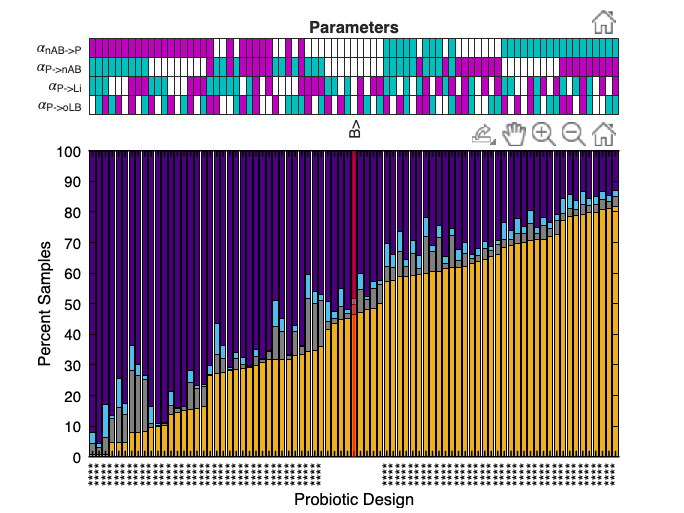

ylim([0,100])